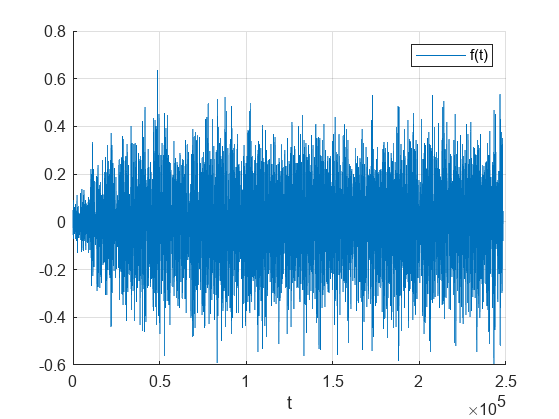

[aud,F] = audioread('MUHA.wav'); %F - частота дискретизации
f0 = figure;
hold on
grid on
plot(aud)
xlabel('t')
legend('f(t)')
saveas(f0,'C:\LATEX\Fourier_analiz\Fourier_3\music_1.png');

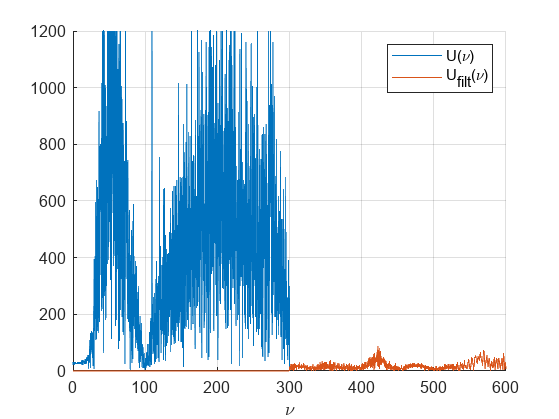

dt = 1/F;
T = length(y)*dt;
t = 0:dt:T-dt; t = t.';

dv = 1/T; % Шаг частоты
v = -F/2 : dv : F/2-dv; % Набор частот для FFT

U = fftshift(fft(aud)); %образ зашумленного
U = U.';

FILT = 1.*(v>=300 | v<=-300); %фильтр
U_filt = FILT.*U; %обрезанный образ
aud_filt = ifft(ifftshift(U_filt)); %обработанный сигнал

f1 = figure; %частотная плоскость (образы)
hold on
plot(v, abs(U)); %модуль образа зашумленной
plot(v, abs(U_filt)); %модуль образа обрезанной
grid on
xlabel("\nu")
xlim([0 600])
ylim([0 1200])
% set(gca, 'XTick', 0:5:300)
legend('U(\nu)', 'U_{filt}(\nu)')
hold off
saveas(f1,'C:\LATEX\Fourier_analiz\Fourier_3\music_2.png');

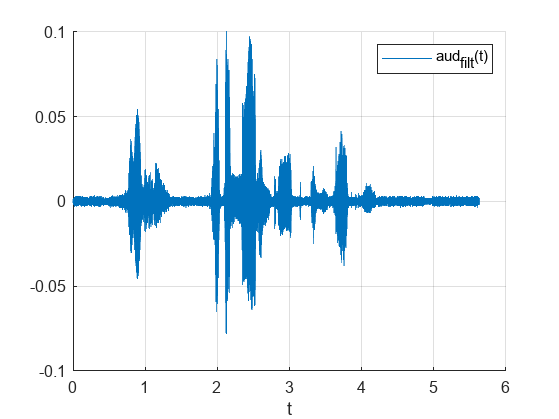


f2 = figure; %временная плосксоть (праобразы)
hold on
plot(t, aud_filt); %обработанный сигнал
grid on
xlabel("t")
legend('aud_{filt}(t)')
hold off
saveas(f2,'C:\LATEX\Fourier_analiz\Fourier_3\music_3.png');



% sound(aud_filt,F);
% audiowrite('C:\LATEX\Fourier_analiz\Fourier_3\music_4.wav',aud_filt,F)